% This script simulates an audiogram

frequencies = [250, 500, 1000, 2000, 3000, 4000, 6000];
dBValuesAudiogram = [-40, -40, -40, -40, -40, -40, -40]; 


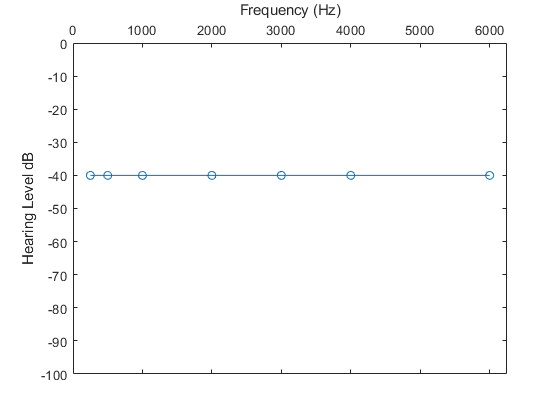

% Plot Audiogram 
plot(frequencies, dBValuesAudiogram,'-o')
xlim([0 6250])
ylim([-100 0])
xlabel('Frequency (Hz)')
ylabel('Hearing Level dB')
set(gca,'xaxisLocation','top')

% insertionGainNAL-R
dBValuesAudiogram = dBValuesAudiogram*-1;
PTA = (dBValuesAudiogram(2) + dBValuesAudiogram(3) + dBValuesAudiogram(4))/3;
X = 0.15*PTA;
C = [-17, -8, 1, -1, -2, -2, -2];
insertionGain = zeros(1, length(dBValuesAudiogram));

for i = 1:length(frequencies)
    insertionGain(1, i) = X + 0.31.*dBValuesAudiogram(i) + C(i);
end

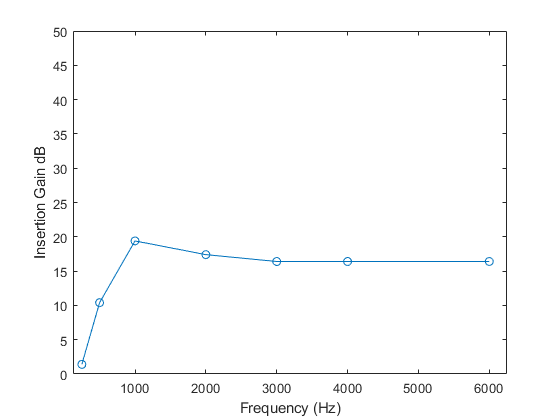

% Plot insertion Gain graph
% Plot Audiogram 
plot(frequencies, insertionGain,'-o')
xlim([125 6250])
ylim([0 50])
xlabel('Frequency (Hz)')
ylabel('Insertion Gain dB')

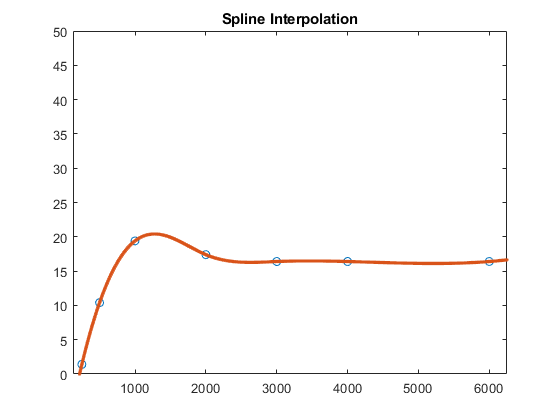

%Interpolate values so the gain constants can be worked out
figure;
xq = 0:1:8000;
vq2 = interp1(frequencies,insertionGain,xq,'spline');
plot(frequencies,insertionGain,'o',xq,vq2,':.')
xlim([125 6250])
ylim([0 50])
title('Spline Interpolation');

%Determine the gain values according to audiogram. 
frequencies;
fmRounded = round(fm);
requiredGainDB = zeros(16, 1);
for i = 1:16
    freq = fmRounded(i);
    requiredGainDB(i, 1) = vq2(freq);
end
requiredGainDB

requiredGainDB =           1.35700196636299
          4.03189258750178
          7.06780564224911
          10.3706206104911
          13.7768893431601
          16.9594480859929
          19.3920447314875
          20.4113051855285
          19.5580146998007
           17.404339780653


% Convert these gain numbers into Constant values
gainConsts = 10.^(requiredGainDB/10)

gainConsts =           1.36678497708092
          2.53040046519935
          5.09073586684383
          10.8908571348445
          23.8610161300181
          49.6529217069555
          86.9369646801695
          109.933617337409
          90.3236480795543
          55.0090288810722


%gainConsts = zeros(16, 1);
%for i = 1:16
 %   gainConsts(i,1) = requiredGainDB(i,1)/10
%end